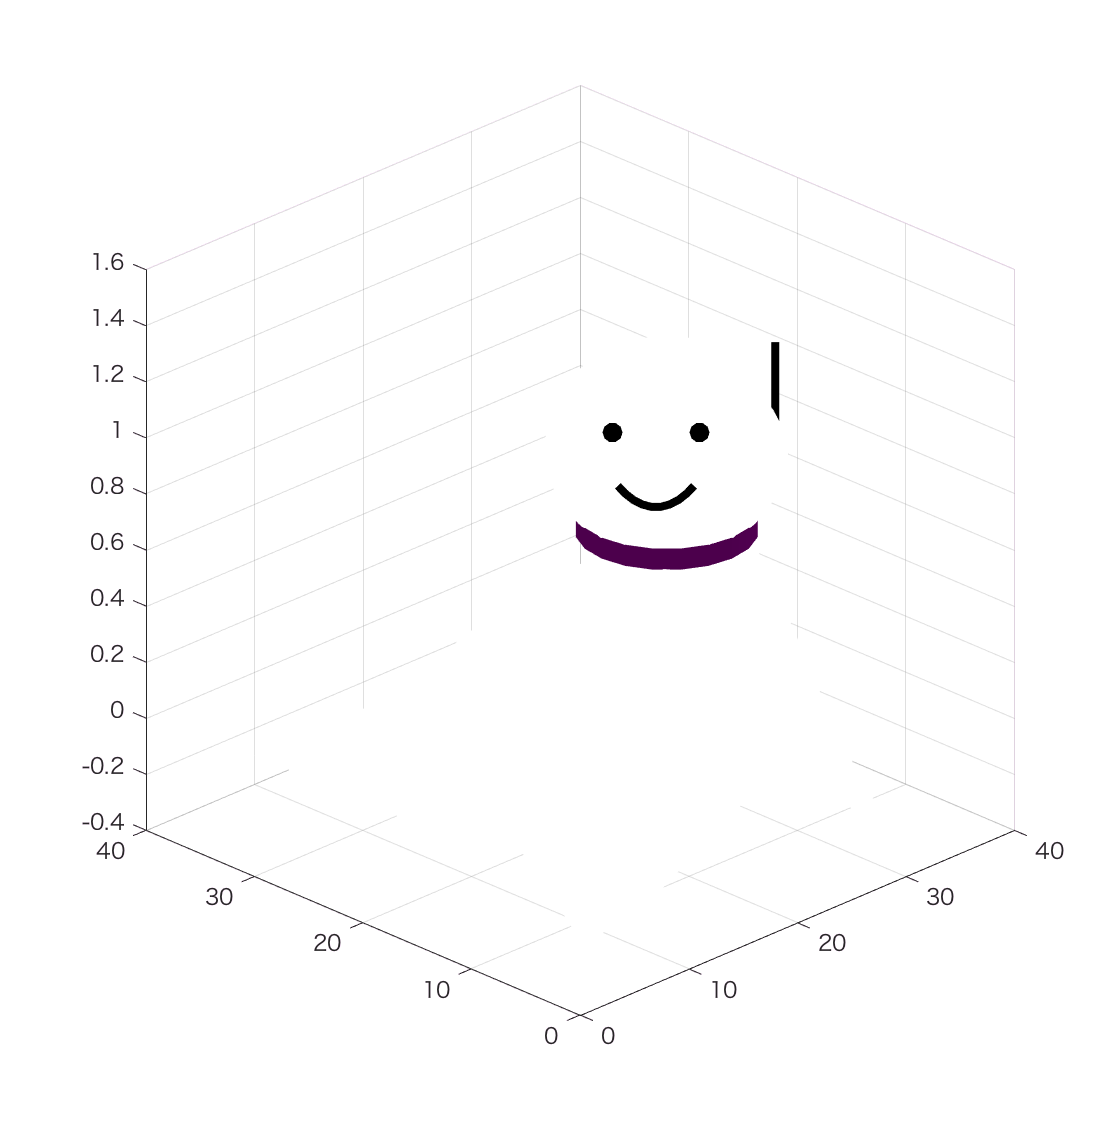

M = membrane(1);
[xs,ys,zs] = sphere;
[xc,yc,zc] = cylinder;

h_fig = figure;
h_fig.Position = [h_fig.Position(1:2) h_fig.Position(3) h_fig.Position(4)+150]; 
surf(M, 'FaceColor', 'w', 'EdgeColor', 'none');

hold on;
surf(8*xs+20,8*ys+12,0.35*zs+1.1, 'FaceColor', 'w', 'EdgeColor', 'none');
surf(6*xc+20,6*yc+12,0.1*zc+0.8, 'FaceColor', 'm', 'EdgeColor', 'none')

plot3(13, 10, 1.3, 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'none', 'MarkerSize', 10);
plot3(17, 6, 1.3, 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'none', 'MarkerSize', 10);

cx = 14; cy = 7; cz = 1.2; r = 1.3;
theta = linspace(pi, 3*pi/2, 10);
X = 2.7*r*cos(theta) + cx;
Y = 2.7*r*sin(theta) + cy;
Z = -0.04*r*sin(2*theta) + cz;

plot3(X, Y, Z, '-k', 'LineWidth', 4);
plot3([24.2 24.2], [6.2 6.2], [1 1.5], 'k', 'LineWidth', 4)

light; 
lighting phong;     % on windows
% lighting gouraud;     % on mac
view(-45, 25)